%% ================= Traitement cinématique multi-sujets ================= %%       
clear; clc; close all;

%% -------- Chargement de l'environnement -------- %%
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\3D Kinematics and Inverse Dynamics'));

%% -------- Sélection des sujets et du mouvement -------- %%
% Liste de tous les sujets à analyser
% Subjects = {...
%     'MF01', 'TF02', 'YL03', 'SC04', 'RF05', 'AP06', ...
%     'TD07', 'IS08', 'LC09', 'MP10', 'PK11', ...
%     'TF12', 'JM13', 'GD14', 'LD15', 'LM16', 'NQ17', 'JV18', ...
%     'EG19', 'MG20', 'LB21', 'AP22', 'SC23', ...
%     'TM24', 'EG25', 'RL26'};

Subjects = {...
    'MF01', 'TF02', 'YL03', 'AP06', ...
    'LC09', 'PK11', ...
    'JM13', 'LD15', 'NQ17', 'JV18', ...
    'MG20', 'SC23', ...
    'TM24', 'EG25'};

movement_choice = 3; % Modifier pour changer de mouvement (1-4)

% Structure pour stocker les résultats de tous les sujets
all_subjects_data = struct();
all_subjects_data.Angles_GH = cell(length(Subjects), 1);
all_subjects_data.Angles_ST = cell(length(Subjects), 1);
all_subjects_data.Angles_HT = cell(length(Subjects), 1);
all_subjects_data.mean_cycles_GH = cell(length(Subjects), 1);
all_subjects_data.mean_cycles_ST = cell(length(Subjects), 1);
all_subjects_data.mean_cycles_HT = cell(length(Subjects), 1);

% Paramètres communs
fs = 200; % Fréquence d'échantillonnage
num_samples_per_cycle = 100; % Nombre d'échantillons pour normaliser les cycles

% Structures pour stocker les moyennes des cycles de tous les sujets
all_subjects_mean_cycles = struct();
all_subjects_mean_cycles.GH = zeros(length(Subjects), num_samples_per_cycle, 3);
all_subjects_mean_cycles.ST = zeros(length(Subjects), num_samples_per_cycle, 3);
all_subjects_mean_cycles.HT = zeros(length(Subjects), num_samples_per_cycle, 3);

%% -------- Traitement de chaque sujet -------- %%
for subj_idx = 1:length(Subjects)
    fprintf('Traitement du sujet %s (%d/%d)...\n', Subjects{subj_idx}, subj_idx, length(Subjects));
    
    % Définition du fichier
    file_names = {... 
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL1-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL2-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL3-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL4-.c3d', Subjects{subj_idx}, Subjects{subj_idx}) ...
    };

    chemin_dossier = sprintf('C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s', Subjects{subj_idx});
    fichier = fullfile(chemin_dossier, file_names{movement_choice});
    
    try
        % Lecture du fichier C3D
        c3dH = btkReadAcquisition(fichier);
        
        %% -------- Extraction des marqueurs -------- %%
        markers = btkGetMarkers(c3dH);
        nFrames = btkGetLastFrame(c3dH);
        time = (0:nFrames-1) / fs;
        time_norm = linspace(0, 1, length(time));
        
        %% -------- Détection des cycles de mouvement basés sur le marqueur RHLE -------- %%
        if isfield(markers, 'RHLE')
            % Calculer la position de référence (moyenne des 100 premières frames)
            RHLE_baseline = mean(markers.RHLE(1:min(100, nFrames), :));
            
            % Calculer la distance euclidienne entre position actuelle et position de référence
            RHLE_distance = sqrt(sum((markers.RHLE - repmat(RHLE_baseline, size(markers.RHLE, 1), 1)).^2, 2));
            
            % Normaliser la distance par rapport à la distance maximale (0-100%)
            RHLE_distance_max = max(RHLE_distance);
            RHLE_distance_normalized = (RHLE_distance / RHLE_distance_max) * 100;
            
            % Filtrage pour lisser la courbe de distance
            fc = 1; % Fréquence de coupure pour le filtre
            [b, a] = butter(2, fc / (fs/2), 'low');
            RHLE_distance_filtered = filtfilt(b, a, RHLE_distance_normalized);
            
            % Détection des cycles basée sur le franchissement d'un seuil
            threshold_pct = 20; % Seuil de la distance maximale (ajustable)
            min_cycle_duration = 0.5 * fs; % Durée minimale d'un cycle (0.5 seconde)
            
            % Initialisation des variables pour détecter les cycles
            cycle_starts = [];
            cycle_ends = [];
            in_cycle = false;
            last_start = 0;
            
            for i = 2:length(RHLE_distance_filtered)
                % Détection du début d'un cycle (franchissement du seuil à la montée)
                if ~in_cycle && RHLE_distance_filtered(i) > threshold_pct && RHLE_distance_filtered(i-1) <= threshold_pct
                    in_cycle = true;
                    last_start = i;
                % Détection de la fin d'un cycle (retour sous le seuil après une durée minimale)
                elseif in_cycle && RHLE_distance_filtered(i) < threshold_pct && RHLE_distance_filtered(i-1) >= threshold_pct && (i - last_start) > min_cycle_duration
                    in_cycle = false;
                    cycle_starts = [cycle_starts, last_start];
                    cycle_ends = [cycle_ends, i];
                end
            end
            
            % Vérification du nombre de cycles détectés
            num_cycles = min(length(cycle_starts), length(cycle_ends));
            
            if num_cycles >= 3
                % Conserver seulement les 3 premiers cycles
                cycle_starts = cycle_starts(1:3);
                cycle_ends = cycle_ends(1:3);
                fprintf('Détection réussie: 3 cycles identifiés pour le sujet %s.\n', Subjects{subj_idx});
            elseif num_cycles > 0
                fprintf('Attention: Seulement %d cycles détectés au lieu de 3 pour le sujet %s.\n', num_cycles, Subjects{subj_idx});
            else
                fprintf('Erreur: Aucun cycle détecté pour le sujet %s. Utilisation de toutes les données.\n', Subjects{subj_idx});
                cycle_starts = 1;
                cycle_ends = nFrames;
                num_cycles = 1;
            end
            
            % Stocker les indices de frames pour chaque cycle
            cycles_frames = cell(num_cycles, 1);
            for i = 1:num_cycles
                cycles_frames{i} = cycle_starts(i):cycle_ends(i);
            end
        else
            warning('Le marqueur RHLE n''est pas disponible pour le sujet %s.', Subjects{subj_idx});
            cycles_frames = {1:nFrames}; % Utiliser toutes les frames si RHLE n'est pas disponible
            num_cycles = 1;
        end
        
        %% -------- Initialisation des matrices pour stocker les angles -------- %%
        Angles_GH = zeros(nFrames, 3);
        Angles_ST = zeros(nFrames, 3);
        Angles_HT = zeros(nFrames, 3);
        normalize_vector = @(v) v / norm(v);
        
        %% ======== Extraction des angles d'Euler selon Wu et al. 2005 ======== %%
        for i = 1:nFrames
            try
                % Etape 1 : Définition des repères segmentaires %

                % Repère du thorax
                SJN = markers.SJN(i,:); CV7 = markers.CV7(i,:);
                TV8 = markers.TV8(i,:); SXS = markers.SXS(i,:);
                Ot = SJN;
                Yt = normalize_vector(mean([SXS; TV8]) - mean([SJN; CV7]));
                Zt = normalize_vector(cross(SJN - CV7, mean([SXS; TV8]) - SJN));
                Xt = normalize_vector(cross(Yt, Zt));
                
                % Repère de la scapula
                RSAA = markers.RSAA(i,:); RSRS = markers.RSRS(i,:); RSIA = markers.RSIA(i,:);
                Os = RSAA;
                Zs = normalize_vector(RSAA - RSRS);
                Xs = normalize_vector(cross(RSIA - RSAA, RSRS - RSAA));
                Ys = normalize_vector(cross(Xs, Zs));
                
                % Repère de l'humérus
                RGH = markers.RSCT(i,:); RHME = markers.RHME(i,:); RHLE = markers.RHLE(i,:);
                Rmid_HLE_HME = mean([RHLE; RHME]);
                Oh = RGH;
                Yh = normalize_vector(RGH - Rmid_HLE_HME);
                Xh = normalize_vector(cross(RGH - RHLE, RGH - RHME));
                Zh = normalize_vector(cross(Yh, Xh));

                % Etape 2 : Calcul des matrices de rotation %

                % Matrices de rotation par rapport au repère global
                Rt = [Xt', Yt', Zt'];
                Rs = [Xs', Ys', Zs'];
                Rh = [Xh', Yh', Zh'];
                
                % Correction orthonormalité (A^T=A = I)
                % Utilisation de "svd" pour garantir que les matrices R sont orthogonales
                [Ut,~,Vt] = svd(Rt); Rt = Ut * Vt';
                [Us,~,Vs] = svd(Rs); Rs = Us * Vs';
                [Uh,~,Vh] = svd(Rh); Rh = Uh * Vh';

                % Matrices de rotation relatives
                R_HT = Rt' * Rh;  % Humérus par rapport au thorax
                R_ST = Rt' * Rs;  % Scapula par rapport au thorax
                R_GH = Rs' * Rh;  % Humérus par rapport à la scapula

                % Etape 3 : Extraction des angles d'Euler selon une séquence spécifique pour chaque angle 
                Angles_HT(i,:) = squeeze(R2mobileYXY_array3(reshape(R_HT,3,3,1))); % Huméro-Thoracique
                Angles_ST(i,:) = squeeze(R2mobileYXZ_array3(reshape(R_ST,3,3,1))); % Scapulo-Thoracique
                Angles_GH(i,:) = squeeze(R2mobileYXY_array3(reshape(R_GH,3,3,1))); % Gléno-Huméral
            catch e
                warning('Erreur lors du calcul des angles à la frame %d pour le sujet %s: %s', i, Subjects{subj_idx}, e.message);
                % Conserver les valeurs précédentes ou mettre NaN
                if i > 1
                    Angles_GH(i,:) = Angles_GH(i-1,:);
                    Angles_ST(i,:) = Angles_ST(i-1,:);
                    Angles_HT(i,:) = Angles_HT(i-1,:);
                else
                    Angles_GH(i,:) = NaN(1,3);
                    Angles_ST(i,:) = NaN(1,3);
                    Angles_HT(i,:) = NaN(1,3);
                end
            end
        end
        
        %% -------- Filtrage et correction des discontinuités -------- %%
        
        % Utilisation de la fonction "unwrap" pour limiter les sauts de cardan liés aux angles de Euler 
        Angles_GH = unwrap(Angles_GH);
        Angles_ST = unwrap(Angles_ST);
        Angles_HT = unwrap(Angles_HT);
        
        % Filtrage passe-bas pour limiter les variations des données des marqueurs et de potentiels données 
        fc = 6;
        [b, a] = butter(2, fc / (fs/2), 'low');
        Angles_GH = filtfilt(b, a, Angles_GH);
        Angles_ST = filtfilt(b, a, Angles_ST);
        Angles_HT = filtfilt(b, a, Angles_HT);
        
        % Recentrage des angles pour éliminer un biais initial (ex : commencer à -200°) et recentrer les courbes
        Angles_GH(:,3) = Angles_GH(:,3) - mean(Angles_GH(1:10,3));
        Angles_ST(:,3) = Angles_ST(:,3) - mean(Angles_ST(1:10,3));
        Angles_HT(:,3) = Angles_HT(:,3) - mean(Angles_HT(1:10,3));
        
        Angles_GH(:,2) = Angles_GH(:,2) - mean(Angles_GH(1:10,2));
        Angles_ST(:,2) = Angles_ST(:,2) - mean(Angles_ST(1:10,2));
        Angles_HT(:,2) = Angles_HT(:,2) - mean(Angles_HT(1:10,2));
        
        Angles_GH(:,1) = Angles_GH(:,1) - mean(Angles_GH(1:10,1));
        Angles_ST(:,1) = Angles_ST(:,1) - mean(Angles_ST(1:10,1));
        Angles_HT(:,1) = Angles_HT(:,1) - mean(Angles_HT(1:10,1));
        
        % Stockage des données pour ce sujet
        all_subjects_data.Angles_GH{subj_idx} = Angles_GH;
        all_subjects_data.Angles_ST{subj_idx} = Angles_ST;
        all_subjects_data.Angles_HT{subj_idx} = Angles_HT;
        
        %% -------- Calcul de la moyenne des cycles pour ce sujet -------- %%
        % Initialisation des matrices pour stocker les cycles moyens
        mean_cycles_GH = zeros(num_samples_per_cycle, 3);
        mean_cycles_ST = zeros(num_samples_per_cycle, 3);
        mean_cycles_HT = zeros(num_samples_per_cycle, 3);
        
        % Interpolation et moyenne des cycles
        for c = 1:3 % Composantes (X, Y, Z)
            % Matrices pour stocker les cycles interpolés
            interp_cycles_GH = zeros(num_cycles, num_samples_per_cycle);
            interp_cycles_ST = zeros(num_cycles, num_samples_per_cycle);
            interp_cycles_HT = zeros(num_cycles, num_samples_per_cycle);
            
            for i = 1:num_cycles
                % Points de temps normalisés pour ce cycle
                cycle_time_norm = linspace(0, 1, length(cycles_frames{i}));
                
                % Points de temps pour l'interpolation
                interp_time = linspace(0, 1, num_samples_per_cycle);
                
                % Récupérer les angles pour ce cycle
                cycle_angles_GH = Angles_GH(cycles_frames{i}, c);
                cycle_angles_ST = Angles_ST(cycles_frames{i}, c);
                cycle_angles_HT = Angles_HT(cycles_frames{i}, c);
                
                % Interpolation des cycles à un nombre fixe d'échantillons
                interp_cycles_GH(i, :) = interp1(cycle_time_norm, cycle_angles_GH, interp_time, 'pchip');
                interp_cycles_ST(i, :) = interp1(cycle_time_norm, cycle_angles_ST, interp_time, 'pchip');
                interp_cycles_HT(i, :) = interp1(cycle_time_norm, cycle_angles_HT, interp_time, 'pchip');
            end
            
            % Calcul de la moyenne des cycles pour chaque composante
            mean_cycles_GH(:, c) = mean(interp_cycles_GH, 1)';
            mean_cycles_ST(:, c) = mean(interp_cycles_ST, 1)';
            mean_cycles_HT(:, c) = mean(interp_cycles_HT, 1)';
        end
        
        % Stockage des cycles moyens pour ce sujet
        all_subjects_data.mean_cycles_GH{subj_idx} = mean_cycles_GH;
        all_subjects_data.mean_cycles_ST{subj_idx} = mean_cycles_ST;
        all_subjects_data.mean_cycles_HT{subj_idx} = mean_cycles_HT;
        
        % Stockage pour le calcul des moyennes globales
        all_subjects_mean_cycles.GH(subj_idx, :, :) = mean_cycles_GH;
        all_subjects_mean_cycles.ST(subj_idx, :, :) = mean_cycles_ST;
        all_subjects_mean_cycles.HT(subj_idx, :, :) = mean_cycles_HT;
        
    catch e
        fprintf('Erreur lors du traitement du sujet %s: %s\n', Subjects{subj_idx}, e.message);
    end
end

Traitement du sujet MF01 (1/14)...


Détection réussie: 3 cycles identifiés pour le sujet MF01.


Traitement du sujet TF02 (2/14)...


Détection réussie: 3 cycles identifiés pour le sujet TF02.


Traitement du sujet YL03 (3/14)...


Détection réussie: 3 cycles identifiés pour le sujet YL03.


Traitement du sujet AP06 (4/14)...


Détection réussie: 3 cycles identifiés pour le sujet AP06.


Traitement du sujet LC09 (5/14)...


Détection réussie: 3 cycles identifiés pour le sujet LC09.


Traitement du sujet PK11 (6/14)...


Détection réussie: 3 cycles identifiés pour le sujet PK11.


Traitement du sujet JM13 (7/14)...


Détection réussie: 3 cycles identifiés pour le sujet JM13.


Traitement du sujet LD15 (8/14)...


Détection réussie: 3 cycles identifiés pour le sujet LD15.


Traitement du sujet NQ17 (9/14)...


Détection réussie: 3 cycles identifiés pour le sujet NQ17.


Traitement du sujet JV18 (10/14)...


Détection réussie: 3 cycles identifiés pour le sujet JV18.


Erreur lors du traitement du sujet JV18: Index exceeds the number of array elements. Index must not exceed 3.


Traitement du sujet MG20 (11/14)...


Détection réussie: 3 cycles identifiés pour le sujet MG20.


Traitement du sujet SC23 (12/14)...


Détection réussie: 3 cycles identifiés pour le sujet SC23.


Erreur lors du traitement du sujet SC23: Index exceeds the number of array elements. Index must not exceed 3.


Traitement du sujet TM24 (13/14)...


Détection réussie: 3 cycles identifiés pour le sujet TM24.


Traitement du sujet EG25 (14/14)...


Détection réussie: 3 cycles identifiés pour le sujet EG25.


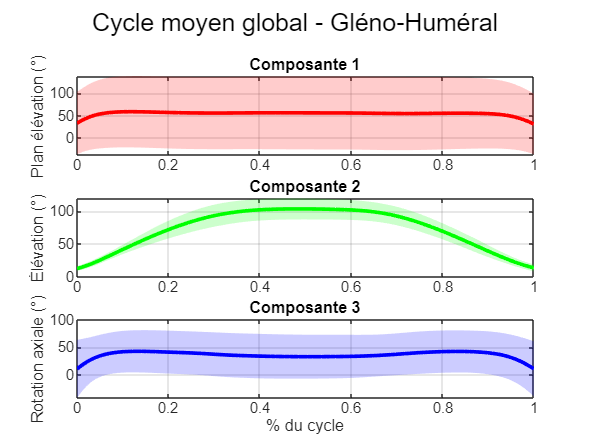


%% -------- Calcul des moyennes et écarts types globaux -------- %%
% Initialisation des matrices pour stocker les moyennes et écarts types
mean_angles_GH = zeros(length(time_norm), 3);
mean_angles_ST = zeros(length(time_norm), 3);
mean_angles_HT = zeros(length(time_norm), 3);

std_angles_GH = zeros(length(time_norm), 3);
std_angles_ST = zeros(length(time_norm), 3);
std_angles_HT = zeros(length(time_norm), 3);

% Compter le nombre de sujets valides
valid_subjects = zeros(length(Subjects), 1);
for subj_idx = 1:length(Subjects)
    if ~isempty(all_subjects_data.Angles_GH{subj_idx})
        valid_subjects(subj_idx) = 1;
    end
end
num_valid_subjects = sum(valid_subjects);

% Calcul des moyennes et écarts types pour les angles complets
for t = 1:length(time_norm)
    for c = 1:3
        % Collecter les valeurs de tous les sujets à cet instant
        GH_values = zeros(num_valid_subjects, 1);
        ST_values = zeros(num_valid_subjects, 1);
        HT_values = zeros(num_valid_subjects, 1);
        
        valid_idx = 0;
        for subj_idx = 1:length(Subjects)
            if valid_subjects(subj_idx) && t <= size(all_subjects_data.Angles_GH{subj_idx}, 1)
                valid_idx = valid_idx + 1;
                GH_values(valid_idx) = all_subjects_data.Angles_GH{subj_idx}(t, c);
                ST_values(valid_idx) = all_subjects_data.Angles_ST{subj_idx}(t, c);
                HT_values(valid_idx) = all_subjects_data.Angles_HT{subj_idx}(t, c);
            end
        end
        
        % Calculer les moyennes et écarts types
        if valid_idx > 0
            mean_angles_GH(t, c) = mean(GH_values(1:valid_idx));
            mean_angles_ST(t, c) = mean(ST_values(1:valid_idx));
            mean_angles_HT(t, c) = mean(HT_values(1:valid_idx));
            
            std_angles_GH(t, c) = std(GH_values(1:valid_idx));
            std_angles_ST(t, c) = std(ST_values(1:valid_idx));
            std_angles_HT(t, c) = std(HT_values(1:valid_idx));
        end
    end
end

% Calcul des moyennes et écarts types pour les cycles moyens
global_mean_cycles = struct();
global_std_cycles = struct();

% Moyennes
global_mean_cycles.GH = squeeze(mean(all_subjects_mean_cycles.GH(valid_subjects==1, :, :), 1));
global_mean_cycles.ST = squeeze(mean(all_subjects_mean_cycles.ST(valid_subjects==1, :, :), 1));
global_mean_cycles.HT = squeeze(mean(all_subjects_mean_cycles.HT(valid_subjects==1, :, :), 1));

% Écarts types
global_std_cycles.GH = squeeze(std(all_subjects_mean_cycles.GH(valid_subjects==1, :, :), 0, 1));
global_std_cycles.ST = squeeze(std(all_subjects_mean_cycles.ST(valid_subjects==1, :, :), 0, 1));
global_std_cycles.HT = squeeze(std(all_subjects_mean_cycles.HT(valid_subjects==1, :, :), 0, 1));

% Temps normalisé pour les figures
cycle_time_norm = linspace(0, 1, num_samples_per_cycle);

%% -------- Affichage des cycles moyens globaux -------- %%
% Figure 1 : Cycles moyens GH globaux avec écarts types
figure;
sgtitle('Cycle moyen global - Gléno-Huméral');

subplot(3,1,1);
plot(cycle_time_norm, rad2deg(global_mean_cycles.GH(:,1)), 'r', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.GH(:,1) + global_std_cycles.GH(:,1))', fliplr(rad2deg(global_mean_cycles.GH(:,1) - global_std_cycles.GH(:,1))')], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Plan élévation (°)');
title('Composante 1');
grid on;

subplot(3,1,2);
plot(cycle_time_norm, rad2deg(global_mean_cycles.GH(:,2)), 'g', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.GH(:,2) + global_std_cycles.GH(:,2))', fliplr(rad2deg(global_mean_cycles.GH(:,2) - global_std_cycles.GH(:,2))')], ...
     'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Élévation (°)');
title('Composante 2');
grid on;

subplot(3,1,3);
plot(cycle_time_norm, rad2deg(global_mean_cycles.GH(:,3)), 'b', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.GH(:,3) + global_std_cycles.GH(:,3))', fliplr(rad2deg(global_mean_cycles.GH(:,3) - global_std_cycles.GH(:,3))')], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Rotation axiale (°)');
xlabel('% du cycle');
title('Composante 3');
grid on;

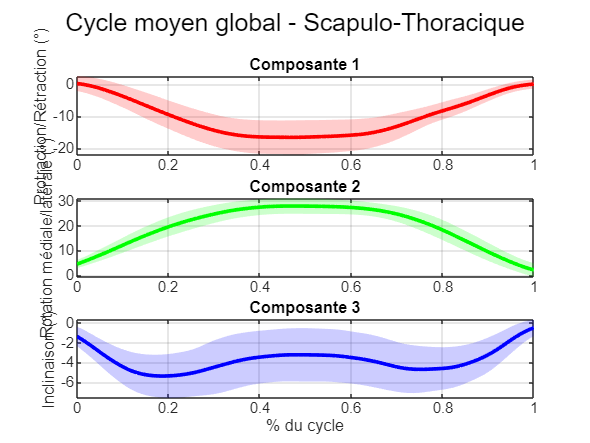


% Figure 2 : Cycles moyens ST globaux avec écarts types
figure;
sgtitle('Cycle moyen global - Scapulo-Thoracique');

subplot(3,1,1);
plot(cycle_time_norm, rad2deg(global_mean_cycles.ST(:,1)), 'r', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.ST(:,1) + global_std_cycles.ST(:,1))', fliplr(rad2deg(global_mean_cycles.ST(:,1) - global_std_cycles.ST(:,1))')], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Protraction/Rétraction (°)');
title('Composante 1');
grid on;

subplot(3,1,2);
plot(cycle_time_norm, rad2deg(global_mean_cycles.ST(:,2)), 'g', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.ST(:,2) + global_std_cycles.ST(:,2))', fliplr(rad2deg(global_mean_cycles.ST(:,2) - global_std_cycles.ST(:,2))')], ...
     'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Rotation médiale/latérale (°)');
title('Composante 2');
grid on;

subplot(3,1,3);
plot(cycle_time_norm, rad2deg(global_mean_cycles.ST(:,3)), 'b', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.ST(:,3) + global_std_cycles.ST(:,3))', fliplr(rad2deg(global_mean_cycles.ST(:,3) - global_std_cycles.ST(:,3))')], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Inclinaison (°)');
xlabel('% du cycle');
title('Composante 3');
grid on;

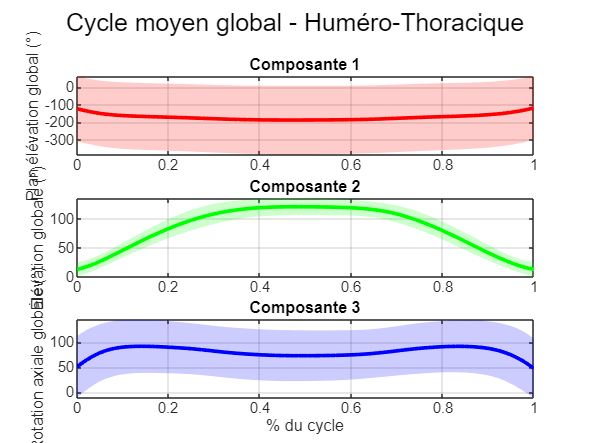


% Figure 3 : Cycles moyens HT globaux avec écarts types
figure;
sgtitle('Cycle moyen global - Huméro-Thoracique');

subplot(3,1,1);
plot(cycle_time_norm, rad2deg(global_mean_cycles.HT(:,1)), 'r', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.HT(:,1) + global_std_cycles.HT(:,1))', fliplr(rad2deg(global_mean_cycles.HT(:,1) - global_std_cycles.HT(:,1))')], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Plan élévation global (°)');
title('Composante 1');
grid on;

subplot(3,1,2);
plot(cycle_time_norm, rad2deg(global_mean_cycles.HT(:,2)), 'g', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.HT(:,2) + global_std_cycles.HT(:,2))', fliplr(rad2deg(global_mean_cycles.HT(:,2) - global_std_cycles.HT(:,2))')], ...
     'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Élévation globale (°)');
title('Composante 2');
grid on;

subplot(3,1,3);
plot(cycle_time_norm, rad2deg(global_mean_cycles.HT(:,3)), 'b', 'LineWidth', 2);
hold on;
fill([cycle_time_norm, fliplr(cycle_time_norm)], ...
     [rad2deg(global_mean_cycles.HT(:,3) + global_std_cycles.HT(:,3))', fliplr(rad2deg(global_mean_cycles.HT(:,3) - global_std_cycles.HT(:,3))')], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylabel('Rotation axiale globale (°)');
xlabel('% du cycle');
title('Composante 3');
grid on;


%% -------- Rapport synthétique -------- %%
fprintf('\n==== Rapport d''analyse ====\n');


==== Rapport d'analyse ====


fprintf('Mouvement analysé: %d\n', movement_choice);

Mouvement analysé: 3


fprintf('Nombre total de sujets: %d\n', length(Subjects));

Nombre total de sujets: 14


fprintf('Nombre de sujets valides: %d\n', num_valid_subjects);

Nombre de sujets valides: 12



% Afficher les statistiques globales
fprintf('\nValeurs moyennes maximales (en degrés):\n');


Valeurs moyennes maximales (en degrés):


fprintf('GH - Plan élévation: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.GH(:,1))), rad2deg(mean(global_std_cycles.GH(:,1))));

GH - Plan élévation: 58.72 ± 80.14


fprintf('GH - Élévation: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.GH(:,2))), rad2deg(mean(global_std_cycles.GH(:,2))));

GH - Élévation: 103.82 ± 12.50


fprintf('GH - Rotation axiale: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.GH(:,3))), rad2deg(mean(global_std_cycles.GH(:,3))));

GH - Rotation axiale: 42.71 ± 39.46



fprintf('\nST - Protraction/Rétraction: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.ST(:,1))), rad2deg(mean(global_std_cycles.ST(:,1))));


ST - Protraction/Rétraction: 0.16 ± 3.87


fprintf('ST - Rotation médiale/latérale: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.ST(:,2))), rad2deg(mean(global_std_cycles.ST(:,2))));

ST - Rotation médiale/latérale: 27.85 ± 3.26


fprintf('ST - Inclinaison: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.ST(:,3))), rad2deg(mean(global_std_cycles.ST(:,3))));

ST - Inclinaison: -0.50 ± 2.19



fprintf('\nHT - Plan élévation global: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.HT(:,1))), rad2deg(mean(global_std_cycles.HT(:,1))));


HT - Plan élévation global: -118.90 ± 191.71


fprintf('HT - Élévation globale: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.HT(:,2))), rad2deg(mean(global_std_cycles.HT(:,2))));

HT - Élévation globale: 120.66 ± 14.41


fprintf('HT - Rotation axiale globale: %.2f ± %.2f\n', rad2deg(max(global_mean_cycles.HT(:,3))), rad2deg(mean(global_std_cycles.HT(:,3))));

HT - Rotation axiale globale: 92.34 ± 52.36
